Jesus Molina Roldan

Victor Vidal Rojas Condori

# Sesion 4

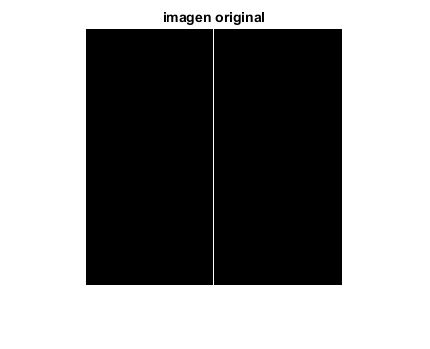

im = false(256);
im(:,128) = 1;
imshow(im), title('imagen original')

**dilatacio1**

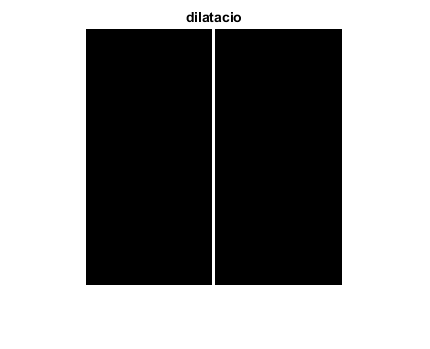

ee = [1 1 1];
row = length(im);
desplazamiento1 = [zeros(1,row);im']';
desplazamiento2 = [im';zeros(1,row)]';
desplazamiento2 = desplazamiento2(:,2:end);
desplazamiento1 = desplazamiento1(:,1:end-1);

dil2 = im | logical(desplazamiento1) | logical(desplazamiento2);
imshow(dil2), title('dilatacio')

**dilatacio2**

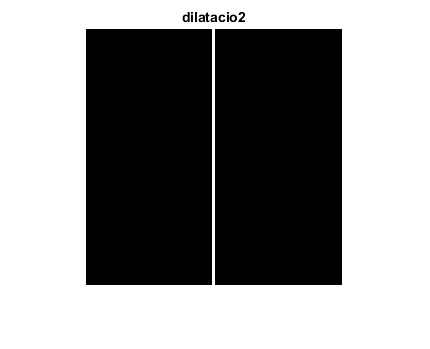

dil = imdilate(im,ee);
figure, imshow(dil), title('dilatacio2')

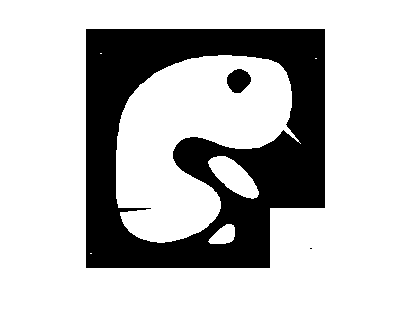

im = imread('blob.tif');
imshow(im)

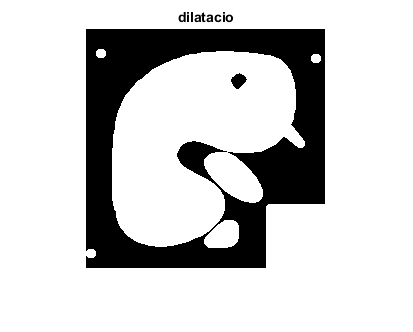

ee = strel('disk',5);
dil = imdilate(im, ee);
ero = imerode(im,ee);
figure,imshow(dil), title('dilatacio')

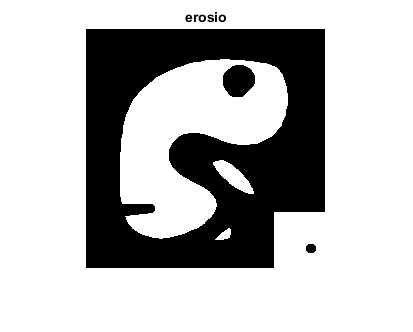

figure, imshow(ero), title('erosio')

**Open Close**

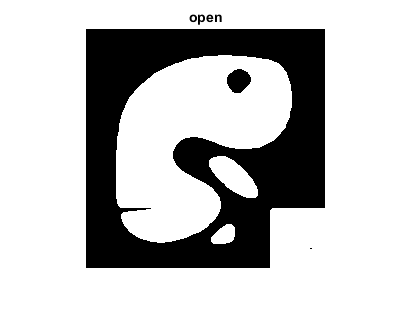

op = imopen(im, ee);
cl = imclose(im,ee);
imshow(op), title('open')

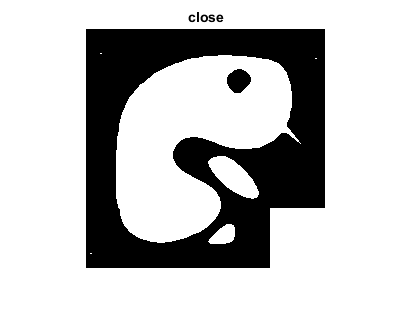

imshow(cl), title('close')

**Dilatacio condicinal**

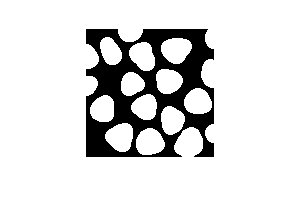

im = imread('blob3.tif');
imshow(im)

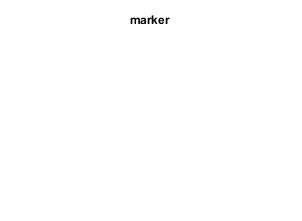

mark=true(128);
mark(2:end-1,2:end-1);
imshow(mark), title('marker')

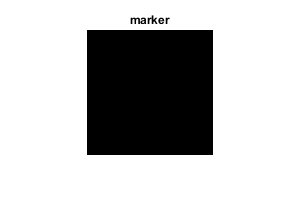

mark(2:end-2,2:end-1) = 0;
imshow(mark), title('marker')

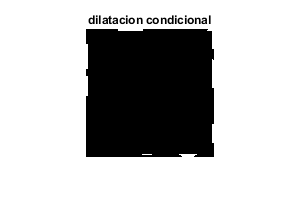

ee = strel('disk',1);
dilc= imdilate(mark,ee)&im;
imshow(dilc), title('dilatacion condicional')

**Reconstruccio**

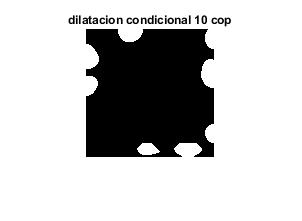

for i = 0:10
    dilc= imdilate(dilc,ee)&im; 
end
imshow(dilc), title('dilatacion condicional 10 cop')

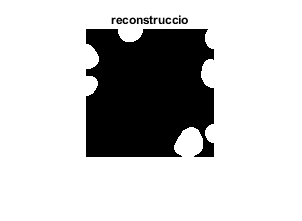

dilc = imreconstruct(mark,im);
imshow(dilc), title('reconstruccio')

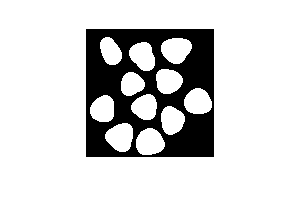

im2 = xor(dilc,im);
imshow(im2)

Problema2

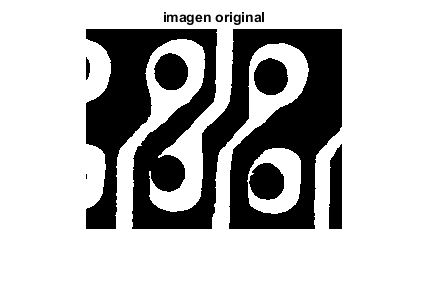

im2 = imread('pcbholes.tif');
imshow(im2), title('imagen original')

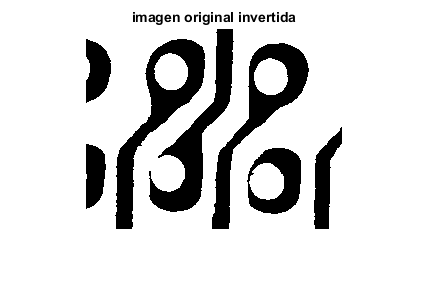

im = ~im2;
imshow(im), title('imagen original invertida') 

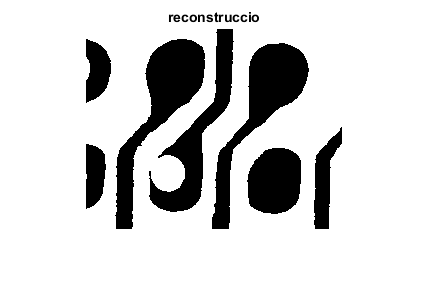

mark=true(200,256);
mark(2:end-1,2:end-1);
%imshow(mark), title('marker');
mark(2:end-2,2:end-1) = 0;
%imshow(mark), title('marker');
ee = strel('disk',1);
dilc= imdilate(mark,ee)&im;
%imshow(dilc), title('dilatacion condicional')
dilc = imreconstruct(mark,im);
imshow(dilc), title('reconstruccio')

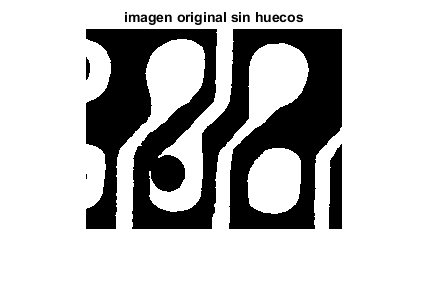

res = ~dilc;
imshow(res), title('imagen original sin huecos')

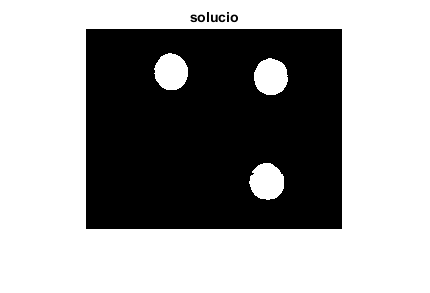

imshow(xor(res, im2)), title('solucio')

**Recuperacio d'objectes**

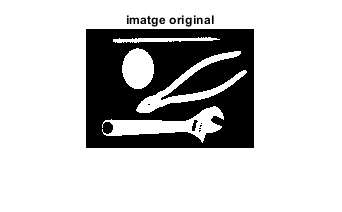

im = imread('tools.tif');
imshow(im), title('imatge original')

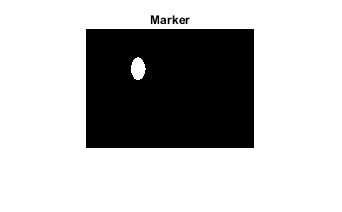

ee = strel('disk',9);
ero = imerode(im,ee);
imshow(ero), title('Marker')

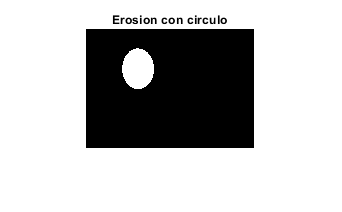

rec1 = imreconstruct(ero,im);
imshow(rec1), title('Erosion con circulo')

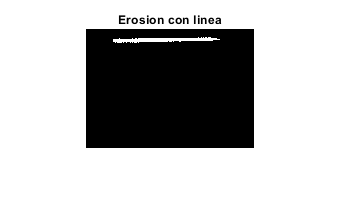


ee =strel('line',100,0);
ero = imerode(im,ee);
rec2 = imreconstruct(ero,im);
imshow(rec2), title('Erosion con linea')

**Problema3**

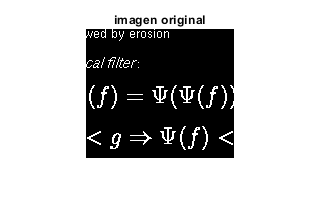

im = imread('letters.tif');
imshow(im), title('imagen original')

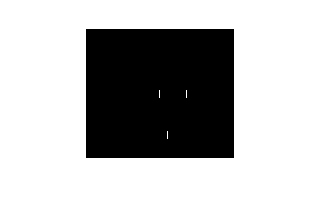

ee = strel('rectangle',[10 2]);
ero = imerode(im,ee);
imshow(ero)

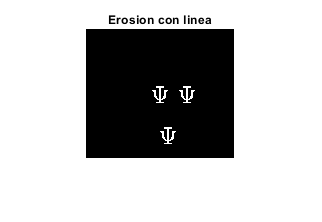

rec2 = imreconstruct(ero,im);
imshow(rec2), title('Erosion con linea')